# Projet 4.5 - Séparation de sources Audio

## Représentation parcimonieuse et acquisitions compressées

Fichier .mlx permettant de tester deux ou trois idées.

Attention, faites en sorte d'avoir :

- Audio Toolbox (Pour importer du son et tout c'est mieux)

- Signal Processing Toolbox 

- Wavelet toolbox (Pour générer les dictionnaires (?))

- Statistics and Machine Learning Toolbox (Pour les algorithmes spécifiques type ICA, clustering, etc..)

- RIP l'espace libre sur vos disques durs.

## Étape 1 - Avoir une source et la caractériser

Déjà, on va ouvrir un signal sur matlab. 

On peut utiliser n'importe quel signal audio. Ici, je ne prendrai que les 20 premières secondes d'un signal , dans le souci de soulager nos processeurs, déjà très sollicités par l'UI de Matlab.

J'ai P=2 observations de mon mélange (les deux mono qui forment le stereo), et N sources. (à voir avec Matthieu Roche ce qu'il a mis comme instrus)

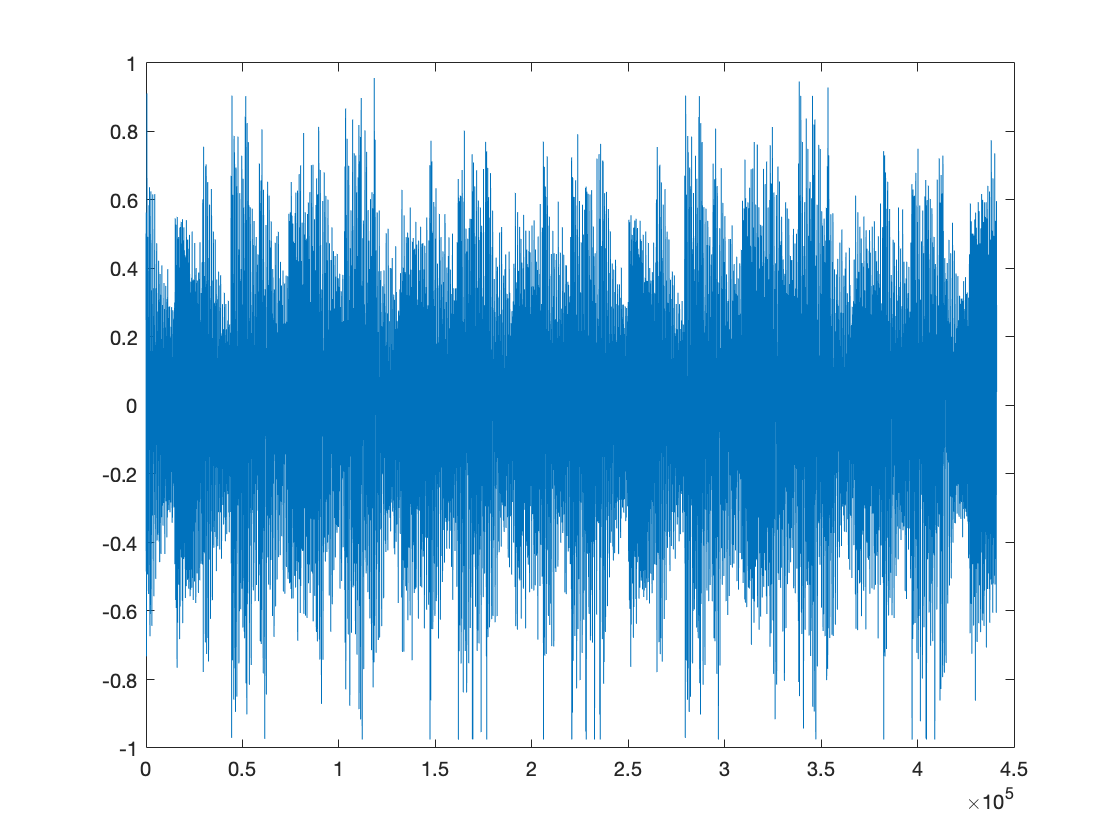

[~,Fs] = audioread('audio_maison.wav');
samples = [1,10*Fs];     %Je ne prends que les 10 premières secondes, sinon mon ordi est à la rue
clear y Fs
[y,Fs] = audioread('audio_maison.wav',samples);
y1 = y(:,1);  %J'ai séparé les deux signaux, parce que Stereo
y2 = y(:,2);

%Nombre d'éléments du signal
len = length(y);
%Durée d'observation, en secondes
Tobs = len / Fs;
%Plot
figure;
title('Signal de départ')
xlabel("Échantillon")
plot(y1);

## Étape 2 - Parcimonier... si on peut le dire comme ça.

Je vais maintenant transformer ce sur quoi je travaille. En effet, je vais passer dans un autre domaine, et utiliser la ***modified discrete cosine transform. ***On qualifiera cette transformée de ***sparsifying linear transform --> ***Elle va rendre nos données parcimonieuses, ou du moins on l'espère. 

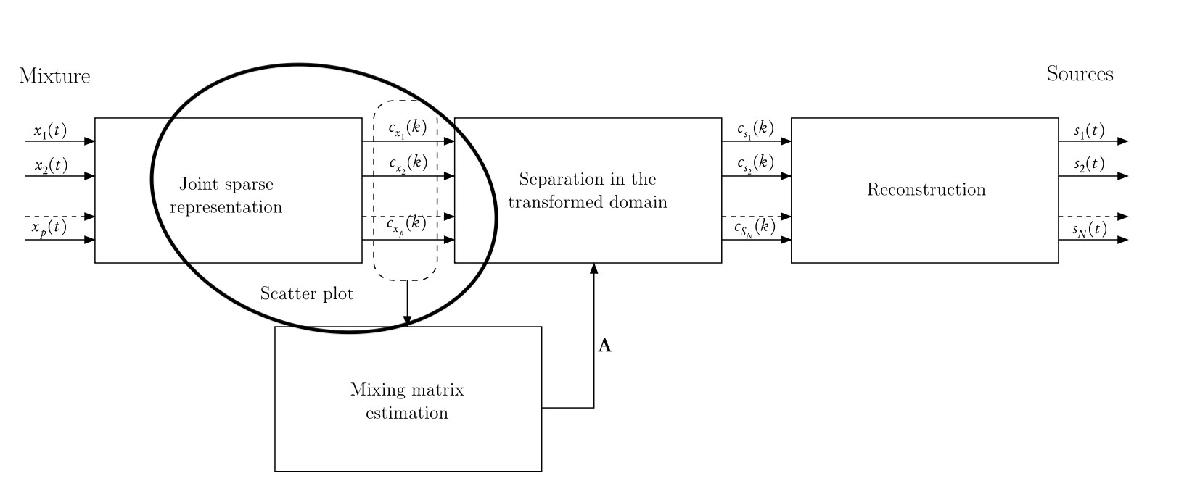

En effet, dans les faits les signaux audio sont tout sauf parcimonieux à la base. C'est un problème à dominantes multiples (Les sources sont actives simultanément), ce qui rend la chose bien plus difficile.  

*Tester d'autres sparsifying transform, peut être? *

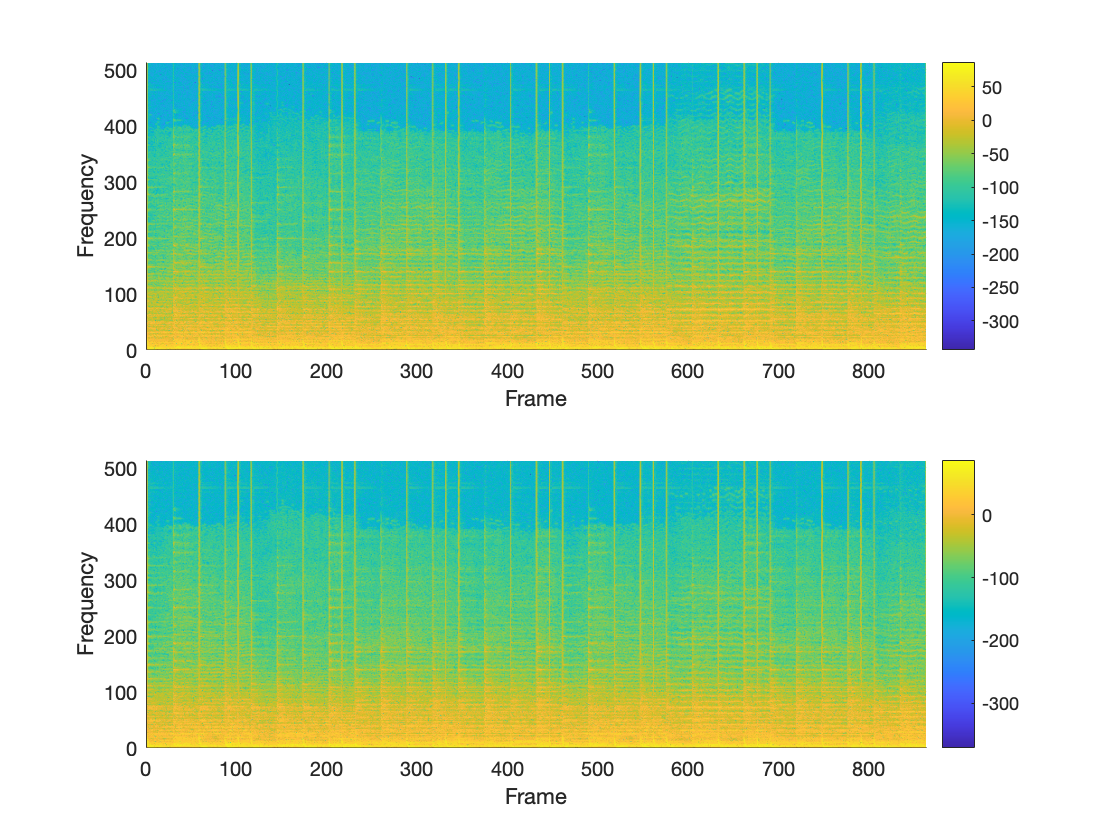

win_size = 1024;
coeffs1 = mdct(y1,kbdwin(win_size));   %renvoie une matrice de la taille de la fenetre sur 2 par
                                            %   ceil(2*length(y1)/1024) +1 
coeffs2 = mdct(y2, kbdwin(win_size));
coeff_size = size(coeffs1);  %Permet de se rendre compte que mdct renvoie une matrice, allez savoir..

subplot(2,1,1);
surf(20*log10(coeffs1.^2),'EdgeColor','none'); %plot une surface
view([0 90])
xlabel('Frame')
ylabel('Frequency')
axis([0 size(coeffs1,2) 0 size(coeffs1,1)])
colorbar
subplot(2,1,2);
surf(20*log10(coeffs2.^2),'EdgeColor','none'); %plot une surface
view([0 90])
xlabel('Frame')
ylabel('Frequency')
axis([0 size(coeffs2,2) 0 size(coeffs2,1)])
colorbar

Tracer l'histogramme permet de voir si on a une distribution parcimonieuse. cf 10.3 du Chap 10 - Handbook blind source separation

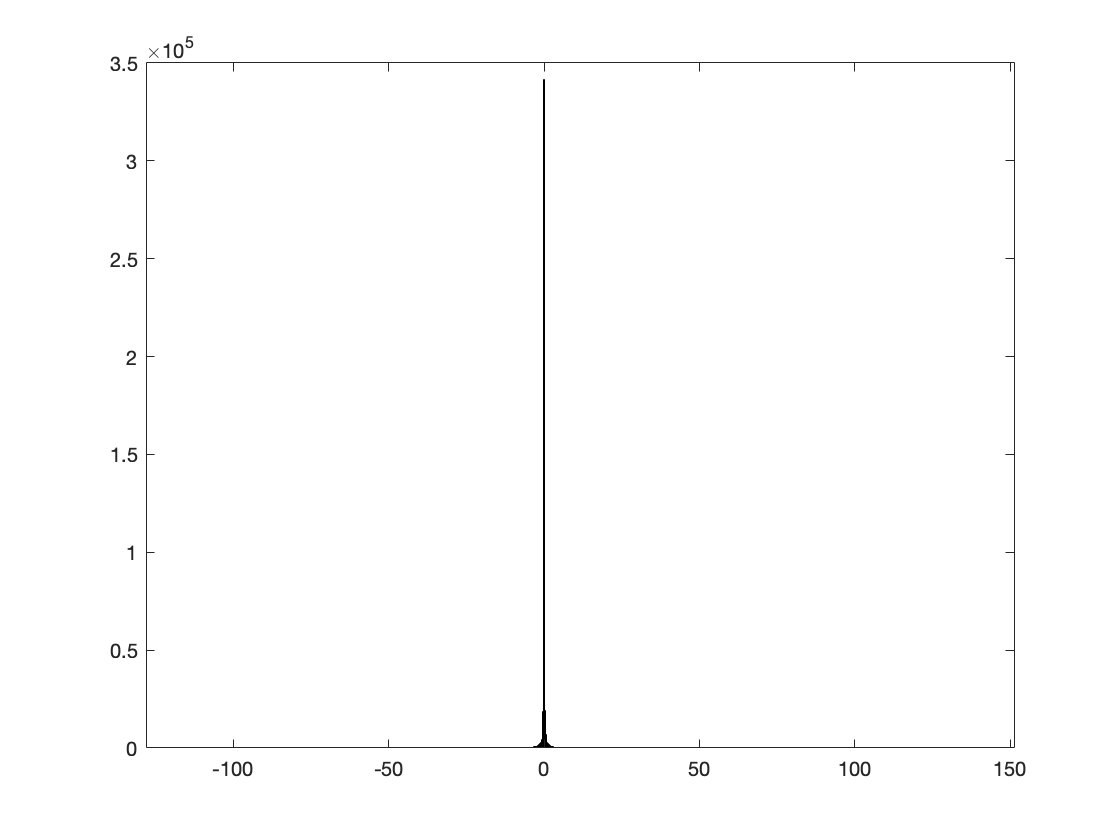

figure;
histogram(coeffs1,1000);    %Assez peu représentatif, on ne se rend pas bien compte de ce qu'il se passe dans voisinage plus petit de 0

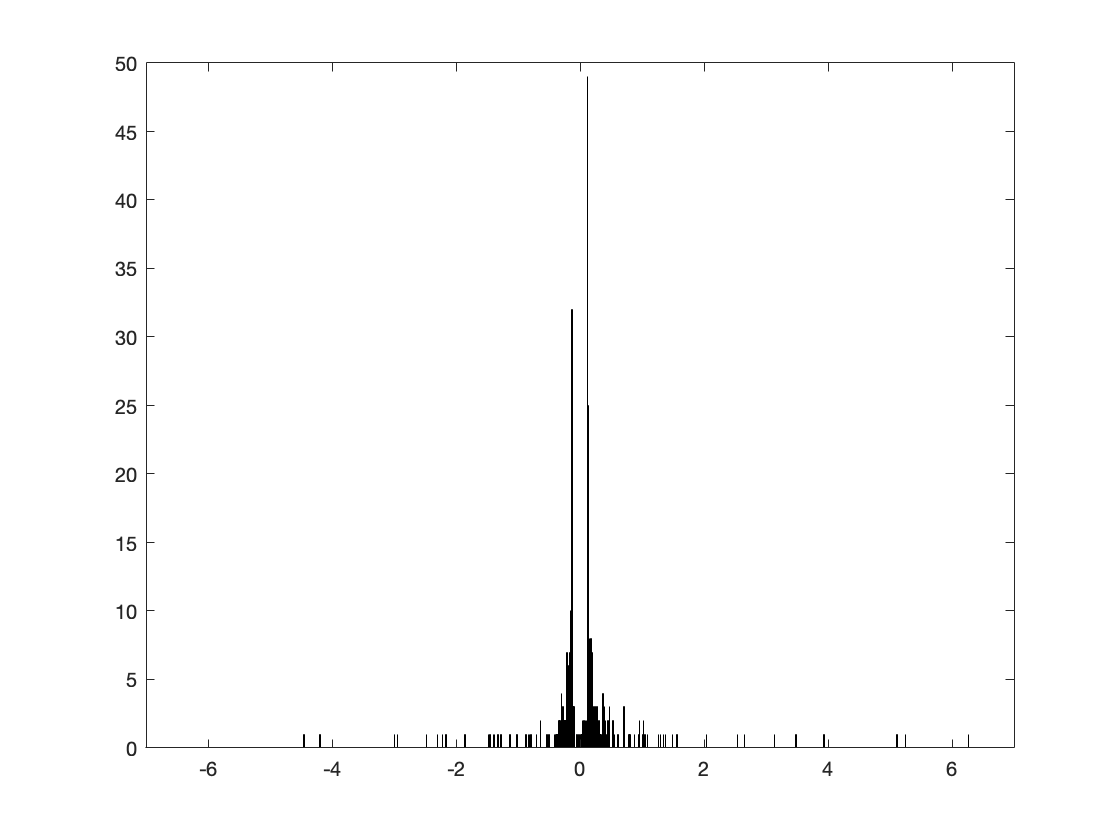

figure;  %Pour regarder de plus près autour de 0
histogram(coeffs1(1:500),10000);
xlim([-7 7])

**Etant donné qu'on a pic pour des valeurs très petites, on peut se dire que c'est le cas : on a plein de valeurs considérées comme quasi-nulles. **

temp = ceil(2*length(y1)/1024) + 1 ;
c1 = reshape(coeffs1,[win_size*temp/2,1]);

c2 = reshape(coeffs2,[win_size*temp/2,1]);    


Des plots non-interprétable pour l'instant.

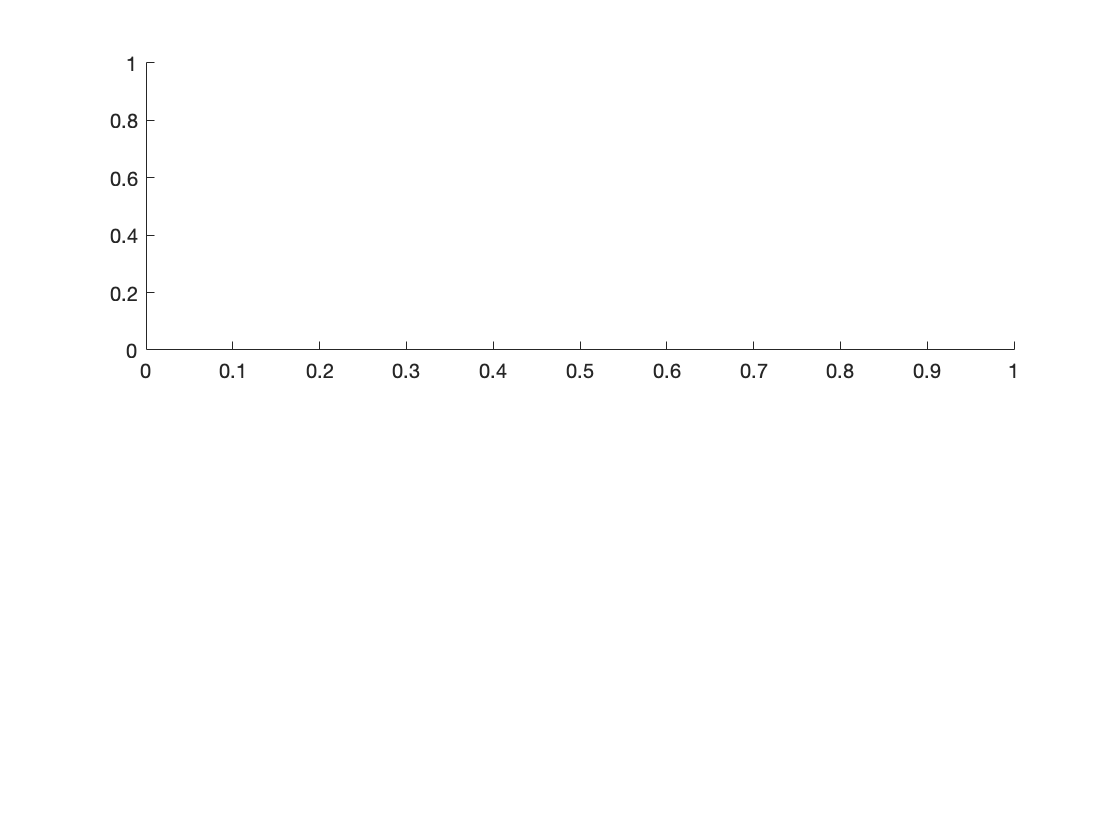

figure;

subplot(2,1,1);

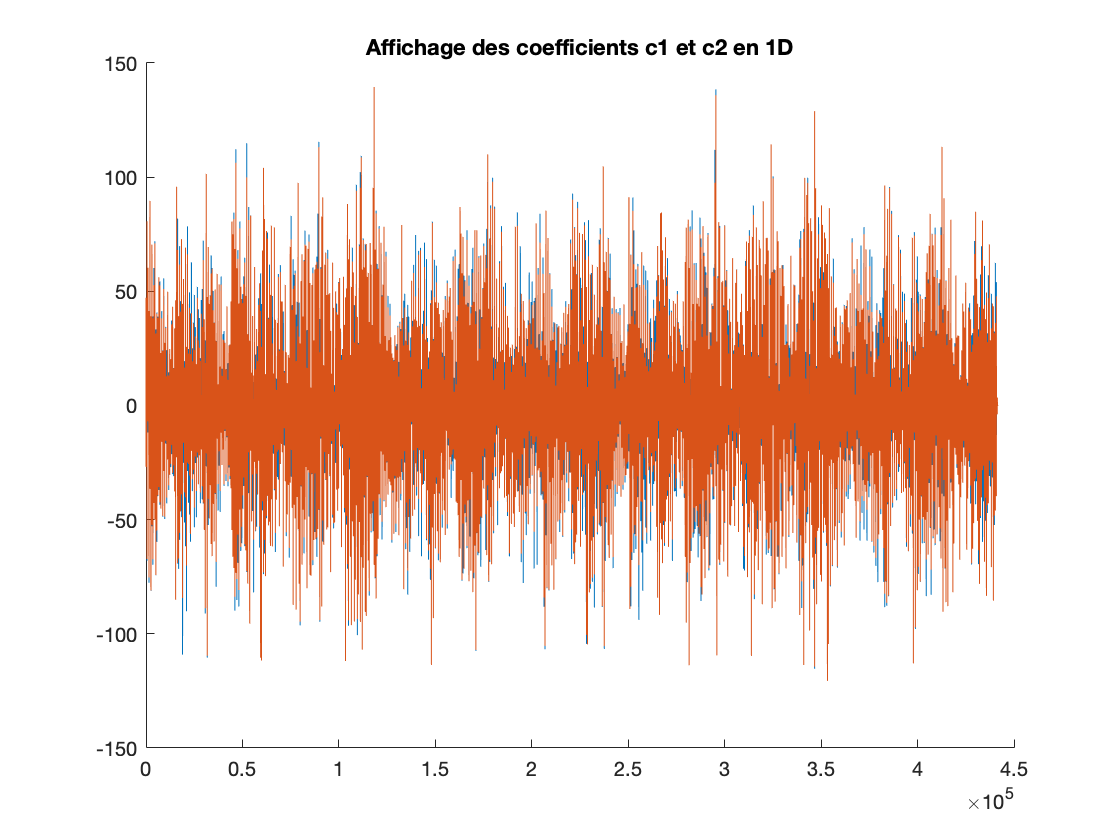

% M1 = mat2gray(coeffs1);
% imshow(M1);
% subplot(2,1,2);
% 
% M2 = mat2gray(coeffs2);
% imshow(M2);
% figure;
% polarplot(coeffs1);

figure;
hold on
plot(c1)
plot(c2)
title("Affichage des coefficients c1 et c2 en 1D")
hold off

## Étape 3 - Estimation de la *Mixing Matrix*

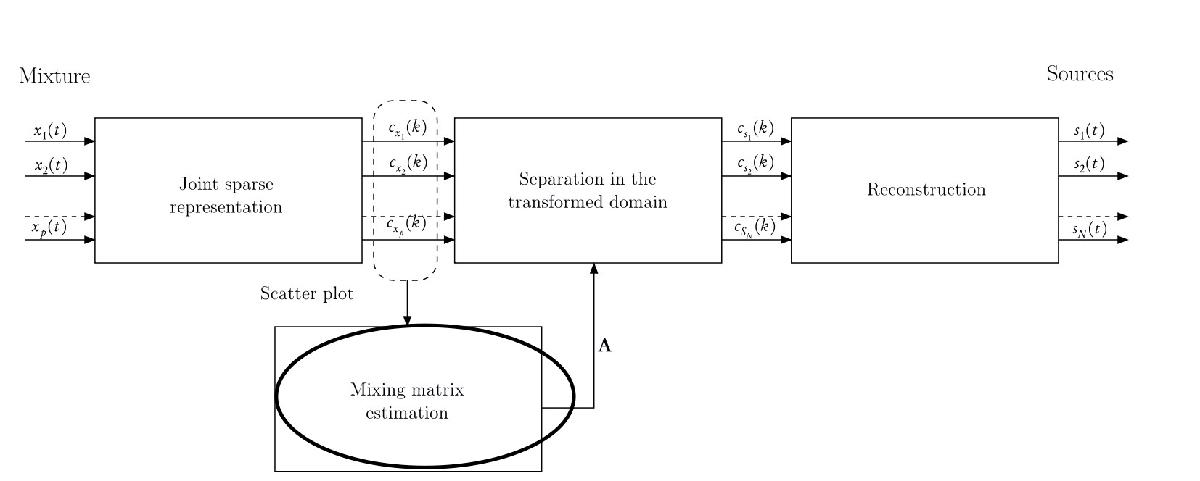

On doit ici estimer la mixing matrix, mais qu'est-ce donc que cela ?

Une matrice, certainement. C'est la matrice qui va représenter le mélange de nos différentes sources, qui composent notre signal final. 

%On va donner le dictionnaire

M = mdct(eye(temp),kbdwin(1024)); %Ne donne pas une matrice 2D.. mais 3D ?! 

%J'ai un gros doute quant à mon utilisation de mdct, et de la fenetre
%kbdwin par défaut.. Il faudra demander aux profs.


## Étape 4 - Séparation en composantes indépendantes

Selon le 2- du 10.1 du Chap 10 - Handbook blind source separation, on peut appliquer un clustering algorithm sur le scatter plot (Mais le scatter plot de quoi?), mais qu'habituellement, on utilise plutôt un algorithme de ICA (independent components analysis). 

J'ai chopé des petites vidéos Yt sympa dessus.

## Étape 5 - Reconstrucion de chaque composante